# Lista 2

**Zad. 1.**  Utwórz wektor `t` o 10 elementach 1,2,3...10. 

t = [1:1:10]

t =      1     2     3     4     5     6     7     8     9    10


Oblicz:


$$x = t\sin(t)$$


x = t.*sin(t)

x =     0.8415    1.8186    0.4234   -3.0272   -4.7946   -1.6765    4.5989    7.9149    3.7091   -5.4402



$$y = \frac{t-1}{t+1}$$


y=(t-1)./(t+1)

y =          0    0.3333    0.5000    0.6000    0.6667    0.7143    0.7500    0.7778    0.8000    0.8182



$$z = \frac{\sin(t^2)}{t^2}$$


z = sin(t.^2)./t.^2

z =     0.8415   -0.1892    0.0458   -0.0180   -0.0053   -0.0275   -0.0195    0.0144   -0.0078   -0.0051


**Zad.2.** Równanie prostej ma postać $y=m\;x+c$, gdzie wartosći $m$ i $c$ są stałe. Oblicz współrzędne $y$przy nachyleniu $m=0\ldotp 5$ oraz $c=-2$ dla następujących współrzędnych $x$:

`x = 0, 1.5, 3, 4, 5, 7, 9, 10.`

m=0.5

m = 0.5000

c=-2

c = -2

x=[0,1.5,3,4,5,7,9,10]

x =          0    1.5000    3.0000    4.0000    5.0000    7.0000    9.0000   10.0000


y=m*x+c

y =    -2.0000   -1.2500   -0.5000         0    0.5000    1.5000    2.5000    3.0000


Proszę narysować otrzymane wyniki poleceniem: `plot(x,y)`

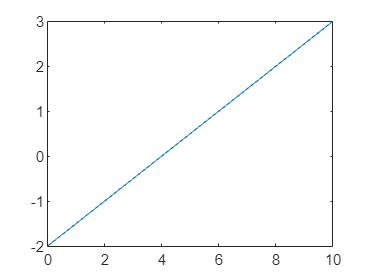

plot(x,y)

**Zad.3** Utwórz tablicę $A\left(10,10\right)$ zawierającą losowe liczby całkowite z przedziału $\left(0,50\right)$. 

A  =round(rand(10,10)*50)

A =     20    17     4    23     5    38    20     1     6    31
    42    30     9     6    30    17     9    30    24    45
    31    45     5     0    12    23    32     6    43    10
    19    35    23    36    42    32    31    20     2    38
    44    19     0    18    43    46    16    44    35    17
    39    37    46    39    48     8    40    27    49    21
    23    48    32    22    24    36    50    18    14     8
    41    27     0    22    11    29    49    10     7    41
    45    27     2     2    11    22     6    22    34    31
    21    16    10     2    27    44    12    48    45    37


Napisz jedną instrukcję, która przekształca tablicę $A$ w następujący sposób:

- usuwa trzeci wiersz

%A(3,:) = []

- usuwa wiersze o parzstych numerach

%A(2:2:size(A,2)-1,:) = []

- zastępuje trzeci wiersz wierszem postaci: 1, 2, 3, ...

%A(3,:) =(1:10)

- dopisuje na dole tablicy wiersz samych jedynek

%A(end,:) = [1]

- zamienia miejscami wiersz 1 i 4

- zamienia miejscami kolumny drugą i ostatnią

**Zad. 4**. Utwórz tablicę $3\times 4$ z losowymi wartościami. Przekształć ją funkcją `reshape()` na wszystkie możliwe sposoby.

tab = round(rand(3,4)*100)

tab =      4    73    55    19
    17    65    30    69
    65    45    74    18


reshape(tab,2,6)

ans =      4    65    65    55    74    69
    17    73    45    30    19    18


reshape(tab,6,2)

ans =      4    55
    17    30
    65    74
    73    19
    65    69
    45    18


reshape(tab,3,4)

ans =      4    73    55    19
    17    65    30    69
    65    45    74    18


reshape(tab,4,3)

ans =      4    65    74
    17    45    19
    65    55    69
    73    30    18


reshape(tab,1,12)

ans =      4    17    65    73    65    45    55    30    74    19    69    18


reshape(tab,12,1)

ans =      4
    17
    65
    73
    65
    45
    55
    30
    74
    19


**Zad. 5.** Utwórz tablicę $3\times 5$ z losowymi wartościami z zakresu -5 do 5 i przechowaj ją w jakiejś zmiennej. Utwórz inną zmienną, w której będą warstości bezwględne elementów pierwszej tablicy.

tab = round(rand(3,5)*10)-5

tab =     -1    -4     0    -2     3
     1     4    -1     0     3
     3     3    -1     0     1


bezwzg = abs(tab)

bezwzg =      1     4     0     2     3
     1     4     1     0     3
     3     3     1     0     1
